clc;clear;

l1 = 203;
l2 = 178;
l3 = 178;

phi1_min = -90;
phi1_max = 90;
phi2_min = -55;
phi2_max = 125;
phi3_min = 0;
phi3_max = 150;

phi1 =0;
phi2 =0;
phi3 =90;

i0 = [50 0 0 1];
j0 = [0 50 0 1];
k0 = [0 0 50 1];
O = [0 0 0 1];

Rotácia R1z

i1 = (rob_rotate('z','deg',phi1)*i0.').';
j1 = (rob_rotate('z','deg',phi1)*j0.').';
k1 = (rob_rotate('z','deg',phi1)*k0.').';

Translácia T2z

A = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*O.').';
i2 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*i0.').';
j2 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*j0.').';
k2 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*k0.').';

Rotácia R3y

i3 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*i0.').';
j3 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*j0.').';
k3 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*k0.').';

Translácia T4z

B = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*O.').';
i4 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*i0.').';
j4 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*j0.').';
k4 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*k0.').';

Rotácia R5y

i5 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*i0.').';
j5 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*j0.').';
k5 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*k0.').';

Translácia T6z

C = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
i6 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*i0.').';
j6 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*j0.').';
k6 = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*k0.').';

Výpočet prac. priestoru xy

xy_iter = 1;
krok = 5;

for(phi1 = phi1_min:krok:phi1_max)
    xy(1:4,xy_iter) = 0;
    for(phi2 = phi2_min:krok:0)
        for(phi3 = phi3_min:krok:phi3_max)
            Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
            Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
            if(xy(4,xy_iter) < Ct(5))
                xy(1:2,xy_iter) = Ct(1:2);
                xy(3,xy_iter) = l1;
                xy(4,xy_iter) = Ct(5);
            end
        end
    end
    xy_iter = xy_iter + 1;
end

for(phi1 = phi1_min:krok:phi1_max)
    xy(1:4,xy_iter) = 0;
    for(phi2 = 0:krok:phi2_max)
        for(phi3 = phi3_min:krok:phi3_max)
            Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
            Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
            if(xy(4,xy_iter) < Ct(5))
                xy(1:2,xy_iter) = Ct(1:2);
                xy(3,xy_iter) = l1;
                xy(4,xy_iter) = Ct(5);
            end
        end
    end
    xy_iter = xy_iter + 1;
end
xy(1:4,xy_iter)=xy(1:4,1);

Výpočet prac. priestoru xz

xz_iter = 1;
krok = 5;

phi1 = 0;
phi2 = phi2_min;

for(phi3 = phi3_min:krok:phi3_max)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

phi3 = phi3_max;

for(phi2 = phi2_min:krok:phi2_max)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

phi2 = phi2_max;

for(phi3 = phi3_max:-krok:phi3_min)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

phi3 = phi3_min;

for(phi2 = phi2_max:-krok:phi2_min)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*O.').';
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

# Vykreslenie údajov

figure; hold on; grid on;
axis equal;
xlim([-400 400]);
ylim([-400 400]);
zlim([-100 600]);
view([40 30])
xlabel('x');
ylabel('y');
zlabel('z');

% Make unit sphere
[x,y,z] = sphere;
% Scale to desire radius.
radius = 7;
x = x * radius;
y = y * radius;
z = z * radius;

Rameno 0-A

plot3([O(1,1),A(1,1)],[O(1,2),A(1,2)],[O(1,3),A(1,3)],'LineWidth',5,'Color','yellow')
surf(x+A(1,1),y+A(1,2),z+A(1,3),'EdgeColor','black','FaceColor','black')

Rameno A-B

plot3([A(1,1),B(1,1)],[A(1,2),B(1,2)],[A(1,3),B(1,3)],'LineWidth',5,'Color','yellow')
surf(x+B(1,1),y+B(1,2),z+B(1,3),'EdgeColor','black','FaceColor','black') 

Rameno B-C

plot3([B(1,1),C(1,1)],[B(1,2),C(1,2)],[B(1,3),C(1,3)],'LineWidth',5,'Color','yellow')
surf(x+C(1,1),y+C(1,2),z+C(1,3),'EdgeColor','black','FaceColor','black')

Súr.Sys A

plot3([A(1,1),i2(1,1)],[A(1,2),i2(1,2)],[A(1,3),i2(1,3)],'Color','red')
plot3([A(1,1),j2(1,1)],[A(1,2),j2(1,2)],[A(1,3),j2(1,3)],'Color','green')
plot3([A(1,1),k2(1,1)],[A(1,2),k2(1,2)],[A(1,3),k2(1,3)],'Color','blue')

Súr.Sys B

plot3([B(1,1),i4(1,1)],[B(1,2),i4(1,2)],[B(1,3),i4(1,3)],'Color','red')
plot3([B(1,1),j4(1,1)],[B(1,2),j4(1,2)],[B(1,3),j4(1,3)],'Color','green')
plot3([B(1,1),k4(1,1)],[B(1,2),k4(1,2)],[B(1,3),k4(1,3)],'Color','blue')

Súr.Sys C

plot3([C(1,1),i6(1,1)],[C(1,2),i6(1,2)],[C(1,3),i6(1,3)],'Color','red')
plot3([C(1,1),j6(1,1)],[C(1,2),j6(1,2)],[C(1,3),j6(1,3)],'Color','green')
plot3([C(1,1),k6(1,1)],[C(1,2),k6(1,2)],[C(1,3),k6(1,3)],'Color','blue')

XY - prac. priestor

fill3(xy(1,:),xy(2,:),xy(3,:),'r','EdgeColor','none','FaceColor','red','FaceAlpha','0.2');
plot3(xy(1,:),xy(2,:),xy(3,:),'Color','red','LineWidth',2);

ABC - prac. priestor

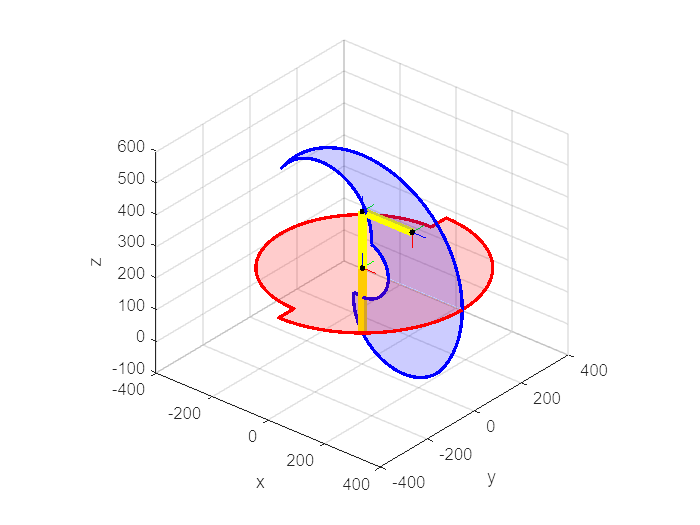

fill3(xz(1,:),xz(2,:),xz(3,:),'b','EdgeColor','none','FaceColor','blue','FaceAlpha','0.2');
plot3(xz(1,:),xz(2,:),xz(3,:),'Color','blue','LineWidth',2);